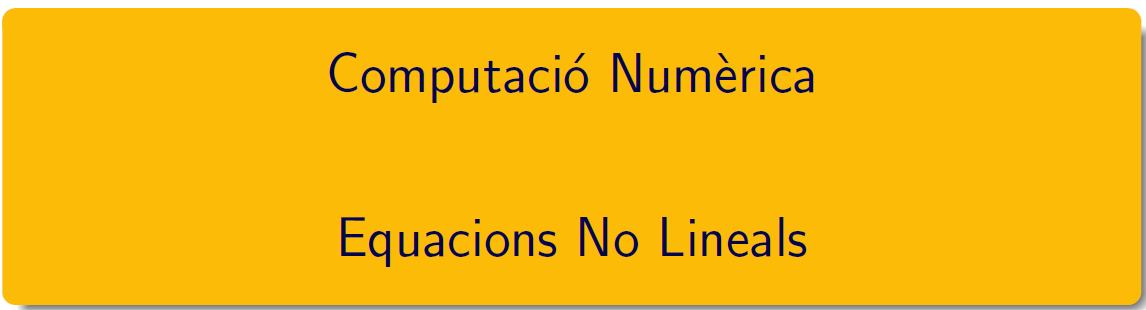

================================================================================

# Pràctica 6. Algorismes clàssics

`by M. Àngela Grau Gotés, març 2023`

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab7.pdf i en el document Exercicis_Tema4.pdf, els podeu trobar en el campus virtual. 

Consulteu els documents [Cleve Moler, Zeroin Algorithms](https://blogs.mathworks.com/cleve/2015/10/12/zeroin-part-1-dekkers-algorithm/)  i el capítol 4 de [Numerical Computing with MATLAB](https://es.mathworks.com/moler/chapters.html), Cleve Moler per a una primera versió dels algorismes de la pràctica.

## 1 Mètode de la bisecció

#### Funció test

- `Determinar l'arrel real del polinomi` $x^3-2x-5 =0$

format longG
p = 2; 
q = 5;
s = sqrt(q^2/4 - p^3/27);
x0 = (q/2 + s)^(1/3) + (q/2 - s)^(1/3)

x0 =           2.09455148154233


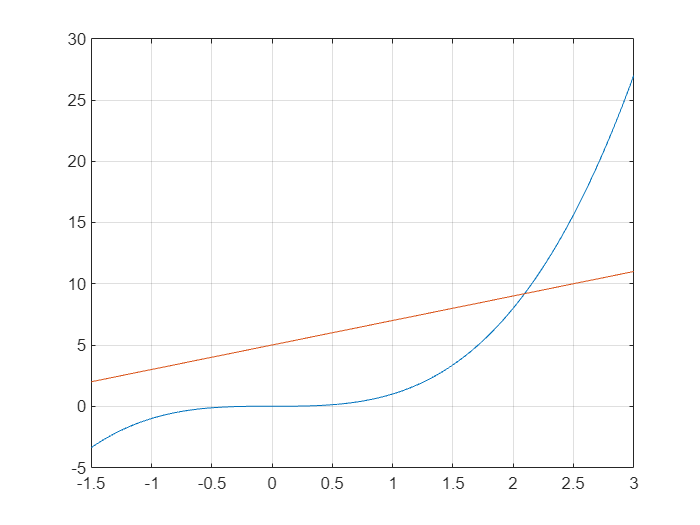

t = linspace(-1.5,3);
plot(t,t.^3,t,2*t+5),grid on

p = [1 0 -2 -5]; 
t=(1.4:0.2:2.4)';
ft = polyval(p,t);
disp(array2table([t,ft],"VariableNames",{'t','f(t)'}))

     t      f(t) 
    ___    ______

    1.4    -5.056
    1.6    -4.104
    1.8    -2.768
      2        -1
    2.2     1.248
    2.4     4.024



#### Pràctiquem.... Algorisme

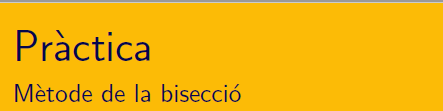

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la bisecció. Els arguments d'entrada han de ser l'interval inicial $$[a,b]$$i la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el punt mig $$\alpha_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

f = @(x)x^3-2*x-5

f = function_handle with value:
    @(x)x^3-2*x-5


a = biseccio(2,2.2,f)

    n           x                    f                      tol         
    __    _____________    _____________________    ____________________

     0                2                       -1                     0.1
     0              2.2                    1.248                     0.1
     1              2.1       0.0610000000000008                     0.1
     2             2.05       -0.484875000000002      0.0500000000000003
     3            2.075       -0.215828124999998      0.0249999999999999
     4           2.0875      -0.0783925781249959      0.0124999999999997
     5          2.09375       -0.008941650390625     0.00625000000000009
     6         2.096875        0.025967742919919     0.00312499999999982
     7        2.0953125      0.00849769973754722     0.00156249999999991
     8       2.09453125    -0.000225810527799908    0.000781

a =              2.09462890625


## 2 Mètode de la tangent

#### Funció test

- ` Calcular la solució ` `de l'equació `$e^x=\displaystyle 2-x$  

p = 2; 
q = 5;
s = sqrt(q^2/4 - p^3/27);
x0 = (q/2 + s)^(1/3) + (q/2 - s)^(1/3)

x0 =           2.09455148154233


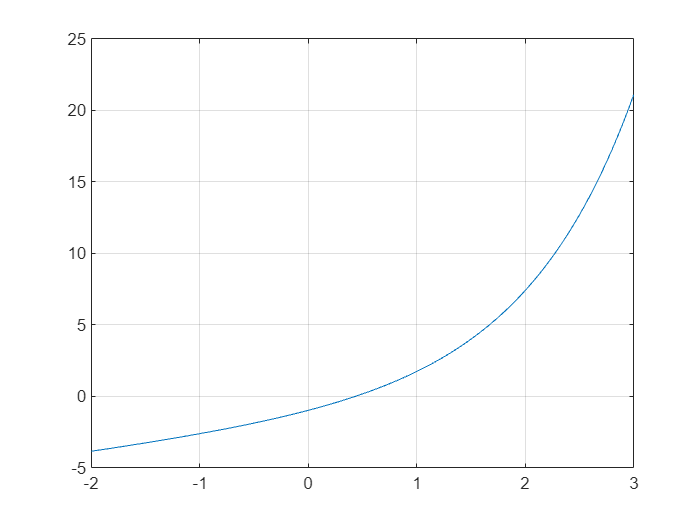

t = linspace(-2,3);
plot(t,-2+t+exp(1).^t),grid on

p = [1 0 -2 -5]; 
t=(1.4:0.2:2.4)';
ft = polyval(p,t);
disp(array2table([t,ft],"VariableNames",{'t','f(t)'}))

     t      f(t) 
    ___    ______

    1.4    -5.056
    1.6    -4.104
    1.8    -2.768
      2        -1
    2.2     1.248
    2.4     4.024



#### Pràctiquem.... Algorisme

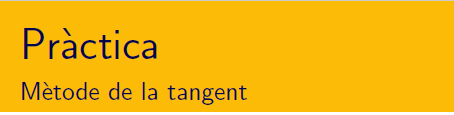

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la tangent. Els arguments d'entrada han de ser lel valor inicial $x_0$ i les funcions $$f$$i $f^\prime$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

f = @(x)exp(1)^x+x-2

f = function_handle with value:
    @(x)exp(1)^x+x-2


fp = @(x)exp(1)^x+1

fp = function_handle with value:
    @(x)exp(1)^x+1


res = tangent(0.4, f, fp)

    n            x                     f                      tol         
    _    _________________    ____________________    ____________________

    0                  0.4       -0.10817530235873                     0.4
    1    0.443412083707625     0.00142631806427751      0.0434120837076248
    2    0.442854495698488    2.42151721785433e-07    0.000557588009136412
    3    0.442854401002391      7.105427357601e-15    9.46960970749089e-08
    4    0.442854401002389                       0    2.77555756156289e-15



res =          0.442854401002389


## 3 Mètode de la secant

#### Funció test

- ` Calcular la solució pròxima a `$x_0=2$ `de l'equació `$\arctan(x)=\displaystyle\frac{2x}{x^2+1}$  

#### Pràctiquem.... Algorisme

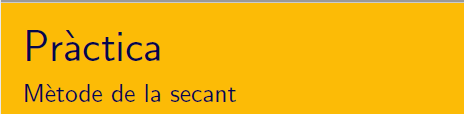

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la secant. Els arguments d'entrada han de ser els valors inicials $x_1$ i $x_2$ i  la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció pels valors de la funció per observar l'acompliment dels criteris d'aturada.

f = @(x)(2*x/((x^2)+1)) - atan(x)

f = function_handle with value:
    @(x)(2*x/((x^2)+1))-atan(x)


res = secant(1.3, 1.4, f)

    n           x                      f                      tol         
    _    ________________    _____________________    ____________________

    0                 1.3       0.0514420503760075                     1.3
    0                 1.4     -0.00460089486612913                     1.4
    1    1.39179041207372    -2.52161541601792e-05     0.00820958792627824
    2    1.39174516977246     1.70099797580647e-08    4.52423012566872e-05
    3    1.39174520027085    -6.13953332617712e-14    3.04983800436531e-08
    4    1.39174520027073                        0    1.10134124042816e-13



res =           1.39174520027073


## 4. Mètode de la iteració simple 

#### Funcions test

- Per a resoldre $x^3=2x+5$  es proposen els mètodes


$$
\mathbf{(f1)}~x_{n+1} = \frac12(x_n^3-5)\,,\qquad \mathbf{(f2)}~x_{n+1} = \sqrt[3]{2x_n+5}\,,$$
 

#### Pràctiquem.... Algorisme

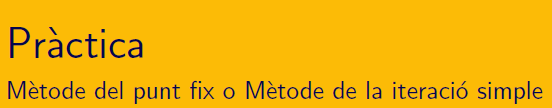

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la iteració simple. Els arguments d'entrada han de ser el valor inicials $x_1$, la funció $$f$$i la funció $g$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció  per observar l'acompliment dels criteris d'aturada.

f = @(x)x^3-2*x-5

f = function_handle with value:
    @(x)x^3-2*x-5


g = @(x)(1/2)*(x^3-5)

g = function_handle with value:
    @(x)(1/2)*(x^3-5)


h = @(x)(2*x+5)^(1/3)

h = function_handle with value:
    @(x)(2*x+5)^(1/3)


res = iteracio(1.4, f, g)

    n              x                         f                        tol         
    _    ______________________    ______________________    _____________________

    0                       1.4                    -5.056                      1.4
    1                    -1.128              -4.179249152                    2.528
    2              -3.217624576          -31.877165303886              2.089624576
    3          -19.156207227943         -6996.25466476132          15.938582651943
    4          -3517.2835396086         -43513304781.7855         3498.12733238066
    5         -21756655908.1763     -1.02985582476275e+31         21756652390.8927
    6     -5.14927912381373e+30      -1.3653352471246e+92     5.14927912381373e+30
    7     -6.82667623562299e+91    -3.18147063468565e+275     6.82667623562299e+91
    8    -1.59073531734282e+275  

res =   -Inf


res2 = iteracio(1.4, f, h)

    n           x                      f                      tol         
    _    ________________    _____________________    ____________________

    0                 1.4                   -5.056                     1.4
    1    1.98319248268077        -1.16638496536155       0.583192482680775
    2    2.07749088512818       -0.188596804894811      0.0942984024474032
    3     2.0919557534705      -0.0289297366846464      0.0144648683423232
    4    2.09415696278154     -0.00440241862208968     0.00220120931104262
    5    2.09449152911744    -0.000669132671800909    0.000334566335900011
    6    2.09454237118723    -0.000101684139568015    5.08420697840073e-05
    7    2.09455009714021    -1.54519059645253e-05    7.72595298270673e-06



res2 =           2.09455009714021


#### Pràctiquem.... Teorema de convergència

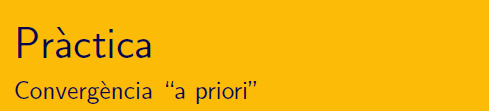

Escriure un `live script de MATLAB® `que:

- analitzi la convergència "a priori" del mètode de la iteració simple $x_{n+1} = g(x_n)$ consistent per a l'equació $f(x)=0$ i obtingui l'interval maximal de convergència en funció de la condició inicial $x_0$

- obtenir el nombre d'iteracions necessàries per acomplit el criteri d'aturada  $tol_x <\epsilon$

function res = biseccio(a, b, f)
    conjx = [a b];
    conjf = [f(a) f(b)];
    tol = abs(b - a)/2;
    na = a;
    nb = b;
    conjn = [0 0];
    conjtol = [tol tol];
    n = 0;
    while tol >= 1*10^-4
        n = n+1;
        x = (nb+na)/2;
        conjx(end+1) = x;
        if (f(na)*f(x)) < 0
            nb = x;
        else
            na = x;
        end
        tol = abs(nb-na);
        conjf(end+1) = f(x);
        res = x;
        conjn(end+1) = n;
        conjtol(end+1) = tol;
    end
    R = [conjn;conjx;conjf;conjtol]';
    T = array2table(R, 'VariableNames',{'n', 'x', 'f', 'tol'});
    disp(T)
end

function res = tangent(x0, f, fp)
    conjx = [x0];
    conjf = [f(x0)];
    conjn = [0];
    conjtol = [x0];
    n = 0;
    x = x0;
    tol = x0;
    res = f(x0);
    while (tol >= 10^-15 && abs(f(x)) >= 10^-15) 
        n = n+1;
        xant = x;
        x = x - f(x)/fp(x);
        tol = abs(x - xant);
        conjx(end+1) = x;
        conjf(end+1) = f(x);
        conjn(end+1) = n;
        conjtol(end+1) = tol;
        res = x;
    end
    R = [conjn;conjx;conjf;conjtol]';
    T = array2table(R, 'VariableNames',{'n', 'x', 'f', 'tol'});
    disp(T)
end

function res = secant(x1, x2, f)
    conjx = [x1 x2];
    conjf = [f(x1) f(x2)];
    conjn = [0 0];
    conjtol = [x1 x2];
    n = 0;
    xm = x1;
    xn = x2;
    tol = abs(x2-x1);
    res = f(x2);
    x = x2;
    while (tol >= 10^-15 && abs(f(x)) >= 10^-15) 
        n = n+1;
        x = xn - f(xn)*(xn-xm)/(f(xn)-f(xm));
        xm = xn;
        tol = abs(x - xn);
        xn = x;
        conjx(end+1) = x;
        conjf(end+1) = f(x);
        conjn(end+1) = n;
        conjtol(end+1) = tol;
        res = x;
    end
    R = [conjn;conjx;conjf;conjtol]';
    T = array2table(R, 'VariableNames',{'n', 'x', 'f', 'tol'});
    disp(T)
end

function res = iteracio(x0, f, g)
    conjx = [x0];
    conjf = [f(x0)];
    conjn = [0];
    conjtol = [x0];
    n = 0;
    x = x0;
    tol = x0;
    res = f(x0);
    while (tol >= 10^-5 && abs(f(x)) >= 10^-5) 
        n = n+1;
        xant = x;
        x = g(x);
        tol = abs(x - xant);
        conjx(end+1) = x;
        conjf(end+1) = f(x);
        conjn(end+1) = n;
        conjtol(end+1) = tol;
        res = x;
    end
    R = [conjn;conjx;conjf;conjtol]';
    T = array2table(R, 'VariableNames',{'n', 'x', 'f', 'tol'});
    disp(T)
end